# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF2_3_Modelling_Regression

## Estimating a Linear Regression Model with OLS

This activity introduces ordinary least squares (OLS) linear regression in MATLAB using a tiny, didactic house-pricing dataset. We'll keep the workflow practical.

**(A short theoretical background is provided at the end of the Live Script.)**

Workflow (the basic one):

- Load a small table of house prices and basic features

- Fit a linear model with fitlm

- Inspect fit quality with the built-in diagnostic plot

- Make a point prediction for a new house profile using predict

**Dataset**

HousePrices is a table file (XLSX) with a numeric response variable Price and a couple of predictors (Size and a simple indicator feature).

This example shows the typical workflow for linear regression analysis using `fitlm`. The general workflow should include preparing a data set, fitting a linear regression model, evaluating and improving the fitted model, and predicting response values for new predictor data. 

In the present example we perform only the very basic steps

% Import data from spreadsheet
HousePrices2 = readtable("C:\Users\mdolf\OneDrive\Documents\Didattica 2026\London\Job\GitHub Materials\HousePrices.xlsx");

% Display results
HousePrices2

HousePrices2 = 47×3 table
    Sfeet    Bedrooms      Price  
    _____    ________    _________

    2104        3        3.999e+05
    1600        3        3.299e+05
    2400        3         3.69e+05
    1416        2         2.32e+05
    3000        4        5.399e+05
    1985        4        2.999e+05
    1534        3        3.149e+05
    1427        3         1.99e+05
    1380        3         2.12e+05
    1494        3        2.425e+05
    1940        4          2.4e+05
    2000        3         3.47e+05
    1890        3          3.3e+05
    4478        5        6.999e+05
    1268        3        2.599e+05
    2300        4        4.499e+05


Fit an OLS linear model using the table; by default the **last column** is treated as the response (set `'ResponseVar','Price'` to be explicit). 


model=fitlm(HousePrices)

model = Linear regression model:
    Price ~ 1 + Sfeet + Bedrooms

Estimated Coefficients:
                    Estimate       SE       tStat       pValue  
                   __________    ______    _______    __________

    (Intercept)    1.0293e+05     52587     1.9573      0.056669
    Sfeet              110.01    17.521     6.2784    1.3143e-07
    Bedrooms           6948.8     19233    0.36129       0.71961


Number of observations: 47, Error degrees of freedom: 44
Root Mean Squared Error: 8.33e+04
R-squared: 0.576,  Adjusted R-Squared: 0.556
F-statistic vs. constant model: 29.9, p-value = 6.44e-09

Show the built-in diagnostic plot: with **one predictor it's data + fitted line; with  multiple predictors it's an added-variable** (partial regression) plot. 

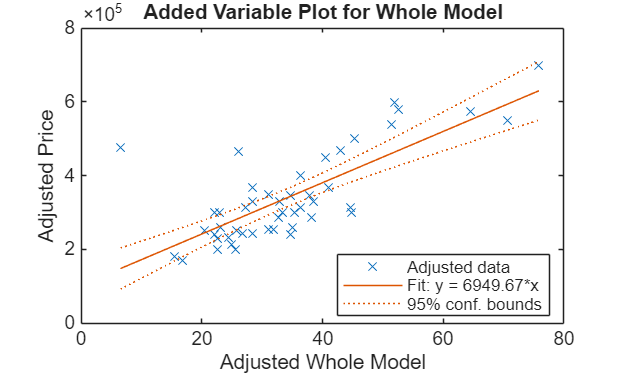


plot(model)

Predict for a new case; when you pass a **matrix/row, columns must match the model's predictor order**. (Using a table with named variables avoids order mistakes.)


estimatedPrice= predict(model,[5000,1]);

fprintf('Estimated price: $%.0f\n', estimatedPrice);

Estimated price: $659908


## Theoretical background (example of unconstrained quadratic optimization).

Model and assumptions

Let $\(y\in\mathbb{R}^{n}\) $ be the response (or regressand), $\(X\in\mathbb{R}^{n\times p}\) $the matrix of regressors, $\(\beta\in\mathbb{R}^{p}\)$ the coefficients, and $$\varepsilon\in\mathbb{R}^{n}$$the errors.


$$y = X\beta + \varepsilon,\qquad \mathbb{E}[\varepsilon]=0,\qquad \mathrm{Var}(\varepsilon)=\sigma^{2}I_n.
\]$$


OLS minimizes the residual sum of squares (RSS):


$$\[
\mathrm{RSS}(\beta)=\|y-X\beta\|_2^2=(y-X\beta)^\top(y-X\beta)
= y^\top y - 2\beta^\top X^\top y + \beta^\top X^\top X\,\beta.
\]$$


Since $\(X^\top X\succeq 0\)$, $\(\mathrm{RSS}(\beta)\)$ is a convex quadratic in $\(\beta\)$. If $\(\mathrm{rank}(X)=p\)$, the minimizer is unique.

Setting the gradient to zero yields the equations:


$$\[
X^\top X\,\hat\beta = X^\top y
\quad\Rightarrow\quad
\hat\beta=(X^\top X)^{-1}X^\top y \quad \text{(\(X^\top X\) is invertible under Gauss-Markov assumptions).}
\]$$


Under Gauss-Markov assumptions:


$$\[
\widehat{\sigma}^{2}=\frac{\mathrm{RSS}(\hat\beta)}{n-p},\qquad
\mathrm{Var}(\hat\beta)=\sigma^{2}(X^\top X)^{-1}\approx \widehat{\sigma}^{2}(X^\top X)^{-1}.
\]$$


"Linear" refers to linearity in the coefficients, not necessarily in the raw predictors. A degree-$\(d\)$ polynomial regression augments predictors:


$$\[
\phi(x)=\big[1,\;x,\;x^{2},\ldots,x^{d}\big],
\]$$


and fits $\(y=\phi(x)\beta+\varepsilon\)$ by OLS. The model is linear in $\(\beta\)$ even though it is nonlinear in $\(x\)$. (In practice, center/scale predictors before adding higher-order terms to mitigate multicollinearity.)

RESET (linearity/specification) 

To probe functional-form misspecification, augment the baseline model with powers of the fitted values, e.g. $\(\hat y^{2}, \hat y^{3}\)$, and test their joint significance. For nested models $\(M_0\)$ (baseline) and $\(M_1\)$ (augmented) with $\(p_0<p_1\)$ parameters and residual sums of squares$ \(\mathrm{RSS}_0,\mathrm{RSS}_1\), the usual nested \(F\)-statistic is
\[$


$$F=\frac{(\mathrm{RSS}_0-\mathrm{RSS}_1)/(p_1-p_0)}{\mathrm{RSS}_1/(n-p_1)}.
\]$$


A small $\(p\)$-value suggests misspecification/nonlinearity in the baseline specification.